clear;
close all;
clc;

addpath("functions/")

fullFileName = get_plotter_data("../data/csv_converted/1.2GHz_10w_4core_merged.csv");
% Extract the name of the file without the path and extension
[~, fileName, ~] = fileparts(fullFileName);

% Create the folder path for the output (ensure the folder exists)
outputFolder = 'images';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder); % Create the folder if it doesn't exist
end

% Create a PNG file name based on the extracted file name and save it in the images folder
outputFileName = fullfile(outputFolder, strcat(fileName, '_nmpc_histogram.png'));

Import the data as a matlab table

data = readtable(fullFileName);

Plot the NMPC histogram

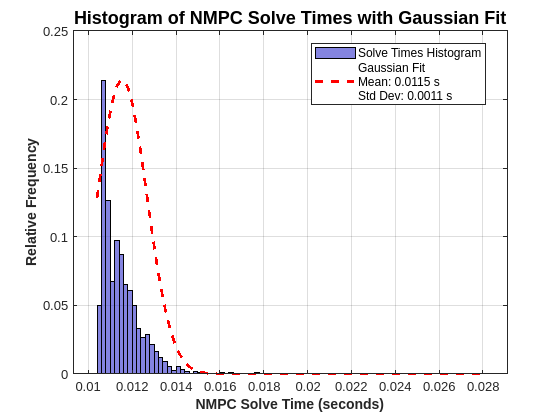

plot_nmpc_histogram(data)
exportgraphics(gcf, outputFileName, 'Resolution', 600);